1.

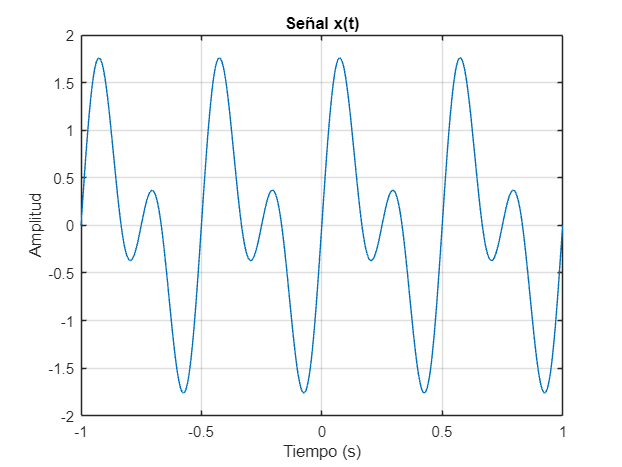

% Definir el rango de tiempo continuo
t = -1:0.001:1;  % De -1 a 1 segundos con un paso de 1 ms

% Definir la señal x(t)
x_t = sin(4*pi*t) + sin(8*pi*t);

% Graficar la señal
figure;
plot(t, x_t);
title('Señal x(t)');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

2.

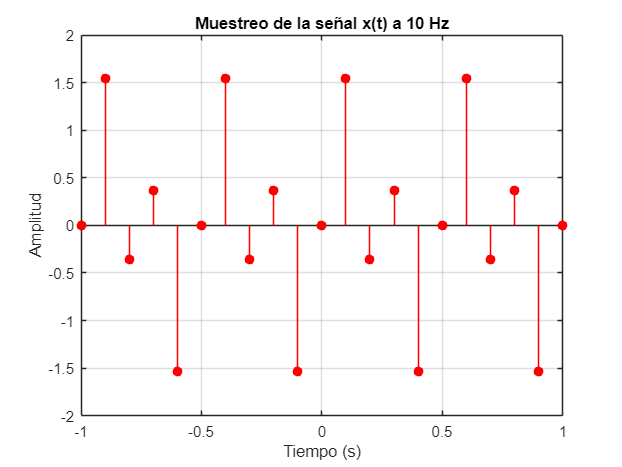

% Definir la frecuencia de muestreo
fs = 10;  % 10 Hz (muestras por segundo)

% Definir el tiempo de muestreo
ts = 1/fs;  % Período de muestreo

% Crear un vector de tiempo discreto
t_discreto = -1:ts:1;  % Desde -1 a 1 segundos con intervalos de muestreo

% Calcular las muestras de la señal
x_discreto = sin(4*pi*t_discreto) + sin(8*pi*t_discreto);

% Graficar las muestras
stem(t_discreto, x_discreto, 'r', 'filled');
title('Muestreo de la señal x(t) a 10 Hz');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

3.

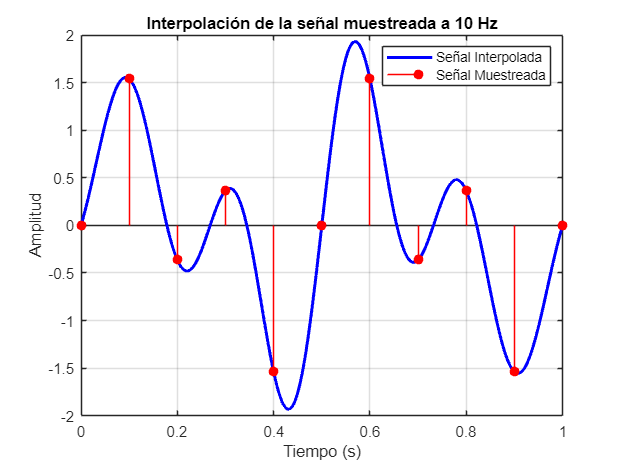

% Definir la frecuencia de muestreo y el periodo de muestreo
Fs = 10;  % 10 Hz
Ts = 1/Fs;  % Periodo de muestreo

% Crear un vector de tiempo discreto para las muestras
t_discreto = 0:Ts:1; 

% Calcular las muestras de la señal
x_discreto = sin(4*pi*t_discreto) + sin(8*pi*t_discreto);

% Crear un vector de tiempo continuo
t_continuo = 0:0.001:1;

% Interpolacion
xa_t = interpolacion(Fs,t_continuo,x_discreto);

% Graficar la señal muestreada y la señal interpolada
figure;
plot(t_continuo, xa_t, 'b', 'LineWidth', 2);  % Señal interpolada en azul
hold on;
stem(t_discreto, x_discreto, 'r', 'filled');  % Señal muestreada en rojo
title('Interpolación de la señal muestreada a 10 Hz');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;
legend('Señal Interpolada', 'Señal Muestreada');

4. 

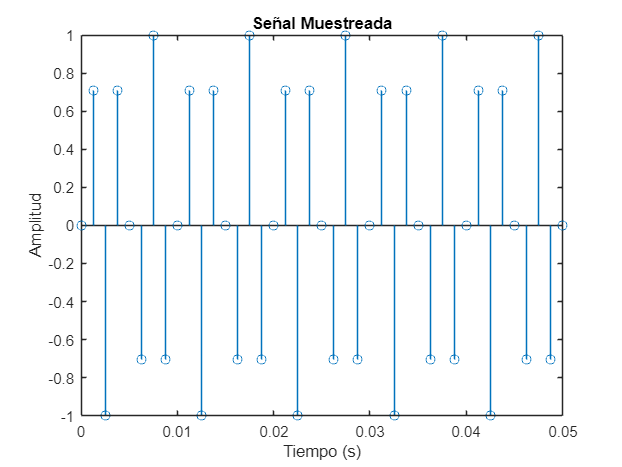

% Parámetros de la señal
amplitud_senal=1;
frecuencia_senal = 300;  % Frecuencia de la señal sinusoidal en Hz
frecuencia_muestreo = 800;  % Frecuencia de muestreo en Hz
t = 0:1/frecuencia_muestreo:0.05;  % Vector de tiempo (Desde 0 hasta 0.05) para verla mejor

% Genera la señal sinusoidal continua
senal = amplitud_senal*sin(2 * pi * frecuencia_senal * t);

% Graficar la señal muestreada

figure;
stem(t, senal);
title('Señal Muestreada');
xlabel('Tiempo (s)');
ylabel('Amplitud');

5.

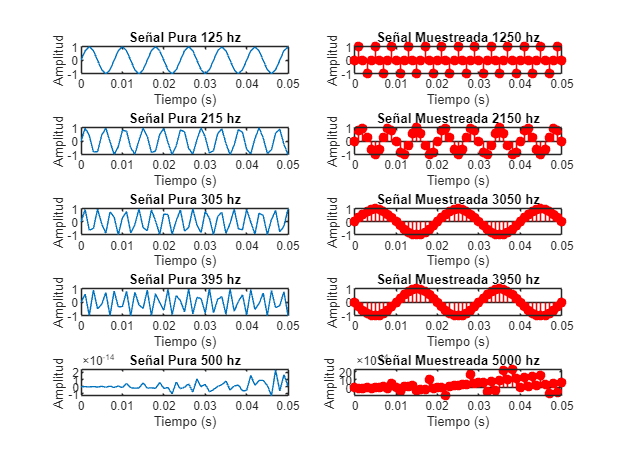

% Parámetros
duracion = 0.05;  % Duración de la señal en segundos
amplitud = 1;  % Amplitud de las señales

% Frecuencias de las señales originales
frecuencias_originales = [125, 215, 305, 395, 500];  % Hz

% Crear un nuevo gráfico
figure;

% Iterar a través de las frecuencias y generar las señales
for i = 1:length(frecuencias_originales)
    f = frecuencias_originales(i);
    
    f_muestreo = 10 * f; %Aumentamos la frecuencia 10 veces

    % Crear un vector de tiempo para la señal pura
    t = 0:0.001:duracion;
    
    % Generar la señal sinusoidal pura
    y_pura = amplitud * sin(2 * pi * f * t);
    
    % Muestrear la señal con la frecuencia de muestreo
    y_muestreada = amplitud * sin(2 * pi * f_muestreo * t);
    
    % Crear subplots para cada señal
    subplot(length(frecuencias_originales), 2, 2 * i - 1);
    plot(t, y_pura);
    title(['Señal Pura ', num2str(f), ' hz']);
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
    
    subplot(length(frecuencias_originales), 2, 2 * i);
    stem(t, y_muestreada, 'r', 'filled');
    title(['Señal Muestreada ', num2str(f_muestreo), ' hz']);
    xlabel('Tiempo (s)');
    ylabel('Amplitud');
end

6.

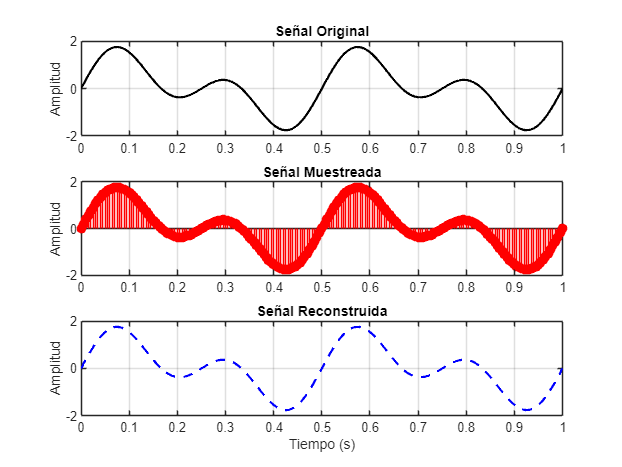

% Parámetros de la señal y muestreo
f_muestreo = 200; % Frecuencia de muestreo en Hz

% Crear vector de tiempo para el muestreo
t_muestreo = 0:1/f_muestreo:1; % 1 segundo de duración

% Señal original muestreada
x_muestreada = sin(4 * pi * t_muestreo) + sin(8 * pi * t_muestreo);

% Crear un vector de tiempo para la señal original y reconstruida
t_hr = 0:0.001:1; 

% Señal original
x_original_hr = sin(4 * pi * t_hr) + sin(8 * pi * t_hr);

% Inicializar la señal reconstruida
x_reconstruida = interpolacion(f_muestreo, t_hr, x_muestreada);

% Graficar la señal original, muestreada y reconstruida en subgráficas
figure;

% Señal original
subplot(3, 1, 1);
plot(t_hr, x_original_hr, 'k', 'LineWidth', 1.5);
title('Señal Original');
ylabel('Amplitud');
grid on;

% Señal muestreada
subplot(3, 1, 2);
stem(t_muestreo, x_muestreada, 'r', 'filled');
title('Señal Muestreada');
ylabel('Amplitud');
grid on;

% Señal reconstruida
subplot(3, 1, 3);
plot(t_hr, x_reconstruida, 'b--', 'LineWidth', 1.5);
title('Señal Reconstruida');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;

Funcion interpolacion

function x_interpolada = interpolacion(Fs, t_cont, x_discreto)
    % Función interna para obtener g
    function g = gt(Fs, x_g)
        g = sin(Fs * pi * x_g) ./ (Fs * pi * x_g); %Calculo de la funcion
        g(isnan(g)) = 1;  % En caso del tiempo 0 e cambia por el 1
    end

    % Inicializa la señal interpolada
    x_interp = zeros(size(t_cont));

    % Realiza la interpolación
    for i = 0:(length(x_discreto)-1)
        g = gt(Fs, t_cont - (i / Fs));  %Obtenemos el valor de g
        aux = x_discreto(i+1) * g;  % Calcular el valor de x por la funcion g para obtener g(t)
        x_interp = x_interp + aux;  %Agregar ese valor porque tiene ceros
    end

    % Devuelve la señal interpolada
    x_interpolada = x_interp;
end
